t = 0 : 0.01 : 2*pi

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f = 1

f = 1

w = 2 * pi * f

w = 6.2832

L = length(t)

L = 629

s = sin(w*t)

s =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


S1 = length(L)

S1 = 1

r = [zeros(1,L), s, zeros(1,2*L), 0.5*s, zeros(1,L)]

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M = length(s) % length of sin(w*t)

M = 629

M2 = length(zeros(1,L)) % length of zeros

M2 = 629

M3 = length(r) % total length

M3 = 3774

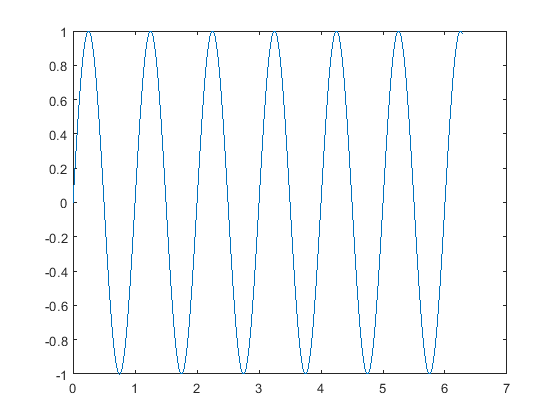

sd = 1;

 r = [zeros(1,L), s , zeros(1,round(2*L)), 0.5*s, zeros(1,L) ]; % 초기 r(t) 
 r1=r+ randn(1,length(r))*sd ;           
 ct1 = length(r)-L;
                    
            for a = 0:ct1
               c(a+1) = r(a+1:a+L)*s'; % 초기 신호 Correlation 함수
            end
            
            plot(t, s)

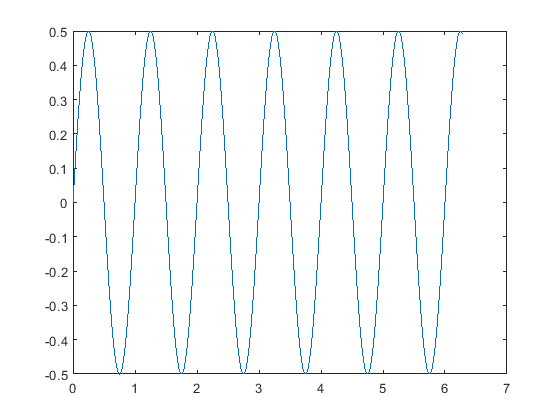

            plot(t, 0.5*s)

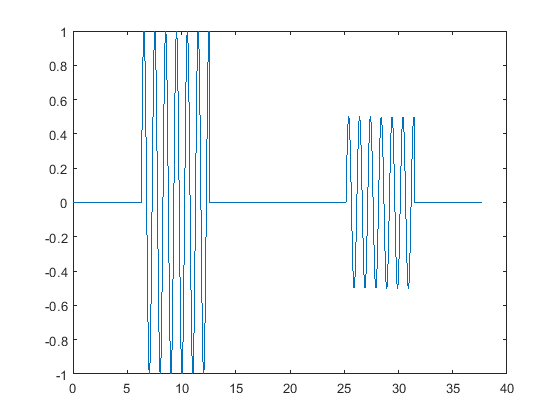

            plot((0:length(r)-1)*0.01, r)

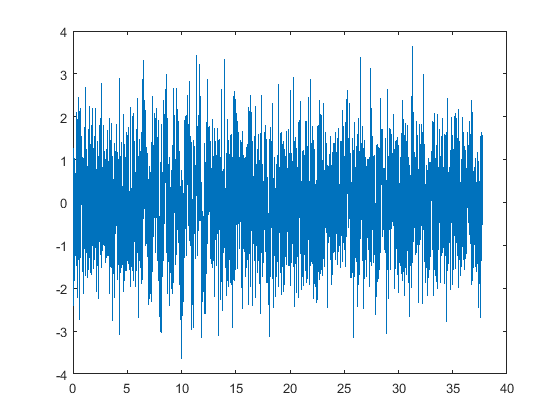

            plot((0:length(r1)-1)*0.01,r1) %sd = 1일때 

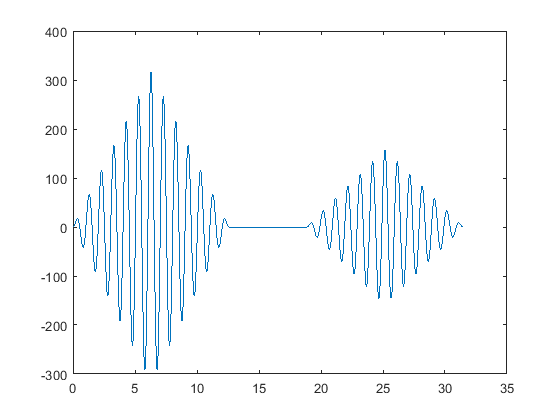

            plot((0:length(c)-1)*0.01, c)

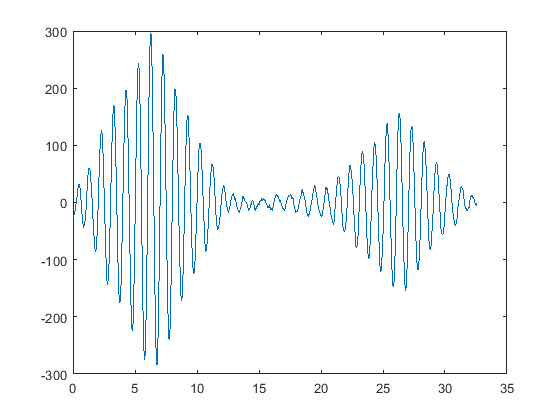

            
%********************************** 거리계산 ********************************

            [m,k1] = max(c);
            c2 = c(length(t)*2 : end);
            [n,k2] = max(c2);
            time_diff = ((length(t)*2+k2-k1))*0.01; % delta_t = 0.01, length(t)*2 = 뒷 신호의 길이
            D = (time_diff/2)*3*10^8*10^-6; % micro second
            
%*********************************************************************            
            clear all;
            t = 0 : 0.01 : 2*pi ;
            f = 1;
            w = 2 * pi * f;
            L = length(t); % 629
            A = 1;
            attenuation = 0.5;    
            SD = 1;
            D= 3000; % 15000m , Time = 1ms
            TL = D/150; % 시간차
            PTP = TL/0.01; % Peak-To-Peak
       y1 = A*sin(w*t);
       y2 = attenuation*A*sin(w*t);
       
%******************K2-K1이 L보다 클 때 ******************************** 

    if( PTP >= L )
         r = [ zeros(1,L), y1, zeros(1, round(PTP)-L), y2, zeros(1, L)];
         r = r + randn(1,length(r))*SD;
         ct1 = length(r) - L;
           for a = 0:ct1
                        c(a+1) = r(a+1:a+L)*y1';
           end
          [m,k1] = max(c);
          c2 = c(length(t)*2 : end);
          [n,k2] = max(c2);
          tl = ((k2+2*length(t))-k1)*0.01; % sec
          D = tl/2*3*100; % m/s
          plot((0:length(c)-1)*0.01, c)
          
     
%***************** K2-K1이 L보다 작을 때 ******************************* 

elseif( PTP < L )
         r = [ zeros(1,L), y1(1:round(PTP)), y2, zeros(1, L)];
         r = r + randn(1,length(r))*SD;
         ct1 = length(r) - L;
           for a = 0:ct1
                        c(a+1) = r(a+1:a+L)*y1';
           end
         r2 = r(L+round(PTP):end);
         ct2 = length(r2) - L;
           for a = 0:ct2
              c2(a+1) = r2(a+1:a+L)*y1'; 
           end
          [m,k1] = max(c);
          [n,k2] = max(c2);
          tl = ((k2+length(t)+round(PTP)+1)-k1)*0.01; % sec (1초당 1샘플)
          D = tl/2*3*100; % m/s 
          subplot(2,1,1)
           plot((0:length(c)-1)*0.01, c)
          subplot(2,1,2)
           plot((0:length(r)-1)*0.01, r)
    end